## Cold plate parameterization 

In this we will carry out a trade-study to investigate different cold plate designs and compare a layout with serpentine U-channles (Figure 1) with a layout with parallel channels (Figure 2). This script is used to vary geometric parameters and compare performance of the two designs in terms of heat transfer and pressure drop. 

The following schematic shows the relevant input parameters that will be used:

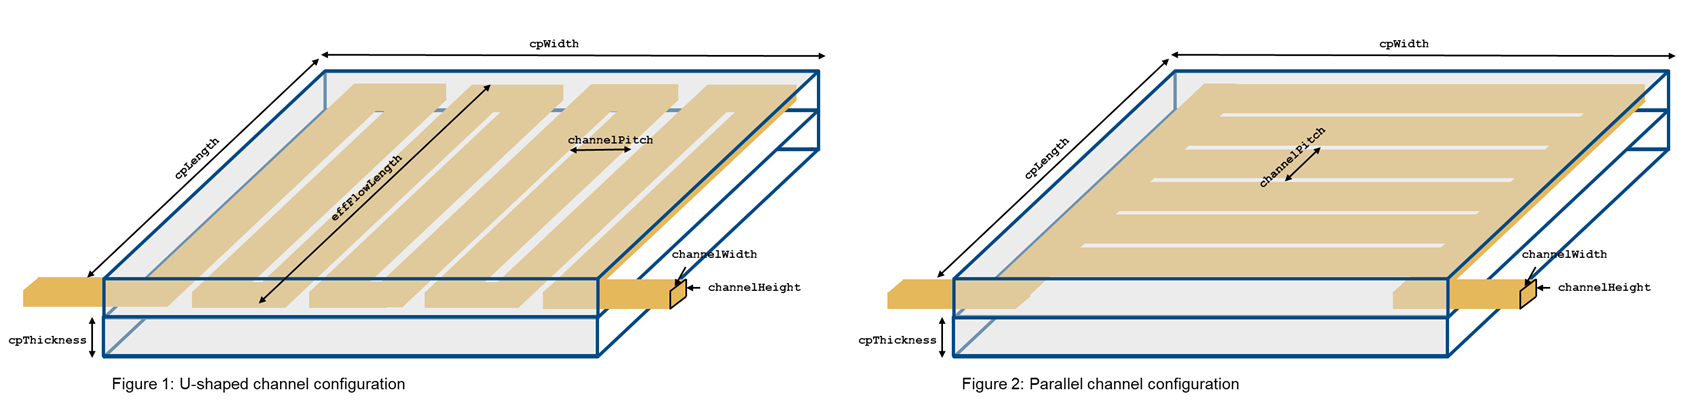

#### Geometric and material parameters of cold plate and cold plate channels:

The U-shaped configuration and the parallel channels configuration will perform differently in terms heat dissipation and pressure drop depending on size of plate and channel geometry. We will perform a parametric sweep across geometric parameter variations and evaluate performance for both configurations by looking at the final device temperature which has to stay below a certain values and the pressure drop across the cold plate. 

For simplicity, we will vary the cold plates length and width, which will largely influence the overall channel length and surface area for convection available. Specifically for the U-shaped confuguration the overall length will contribute significantly to the pressure drop. For different channel areas we will only vary the channel width and leave the channel height at a constant value. 

cpLength            = simscape.Value(180:20:320, "mm");    
cpWidth             = simscape.Value(180:20:320, "mm");    
cpThickness         = simscape.Value(5, "mm");            
        

channelWidth        = simscape.Value( 2:1:4, "mm");         
channelHeight       = simscape.Value( 8, "mm");             
channelMargin       = simscape.Value( 10, "mm");           

### Set up parameter sweep for cold plate configuration

To compare the two configurations both are setup in one model:

open_system("example_compareColdPlates")

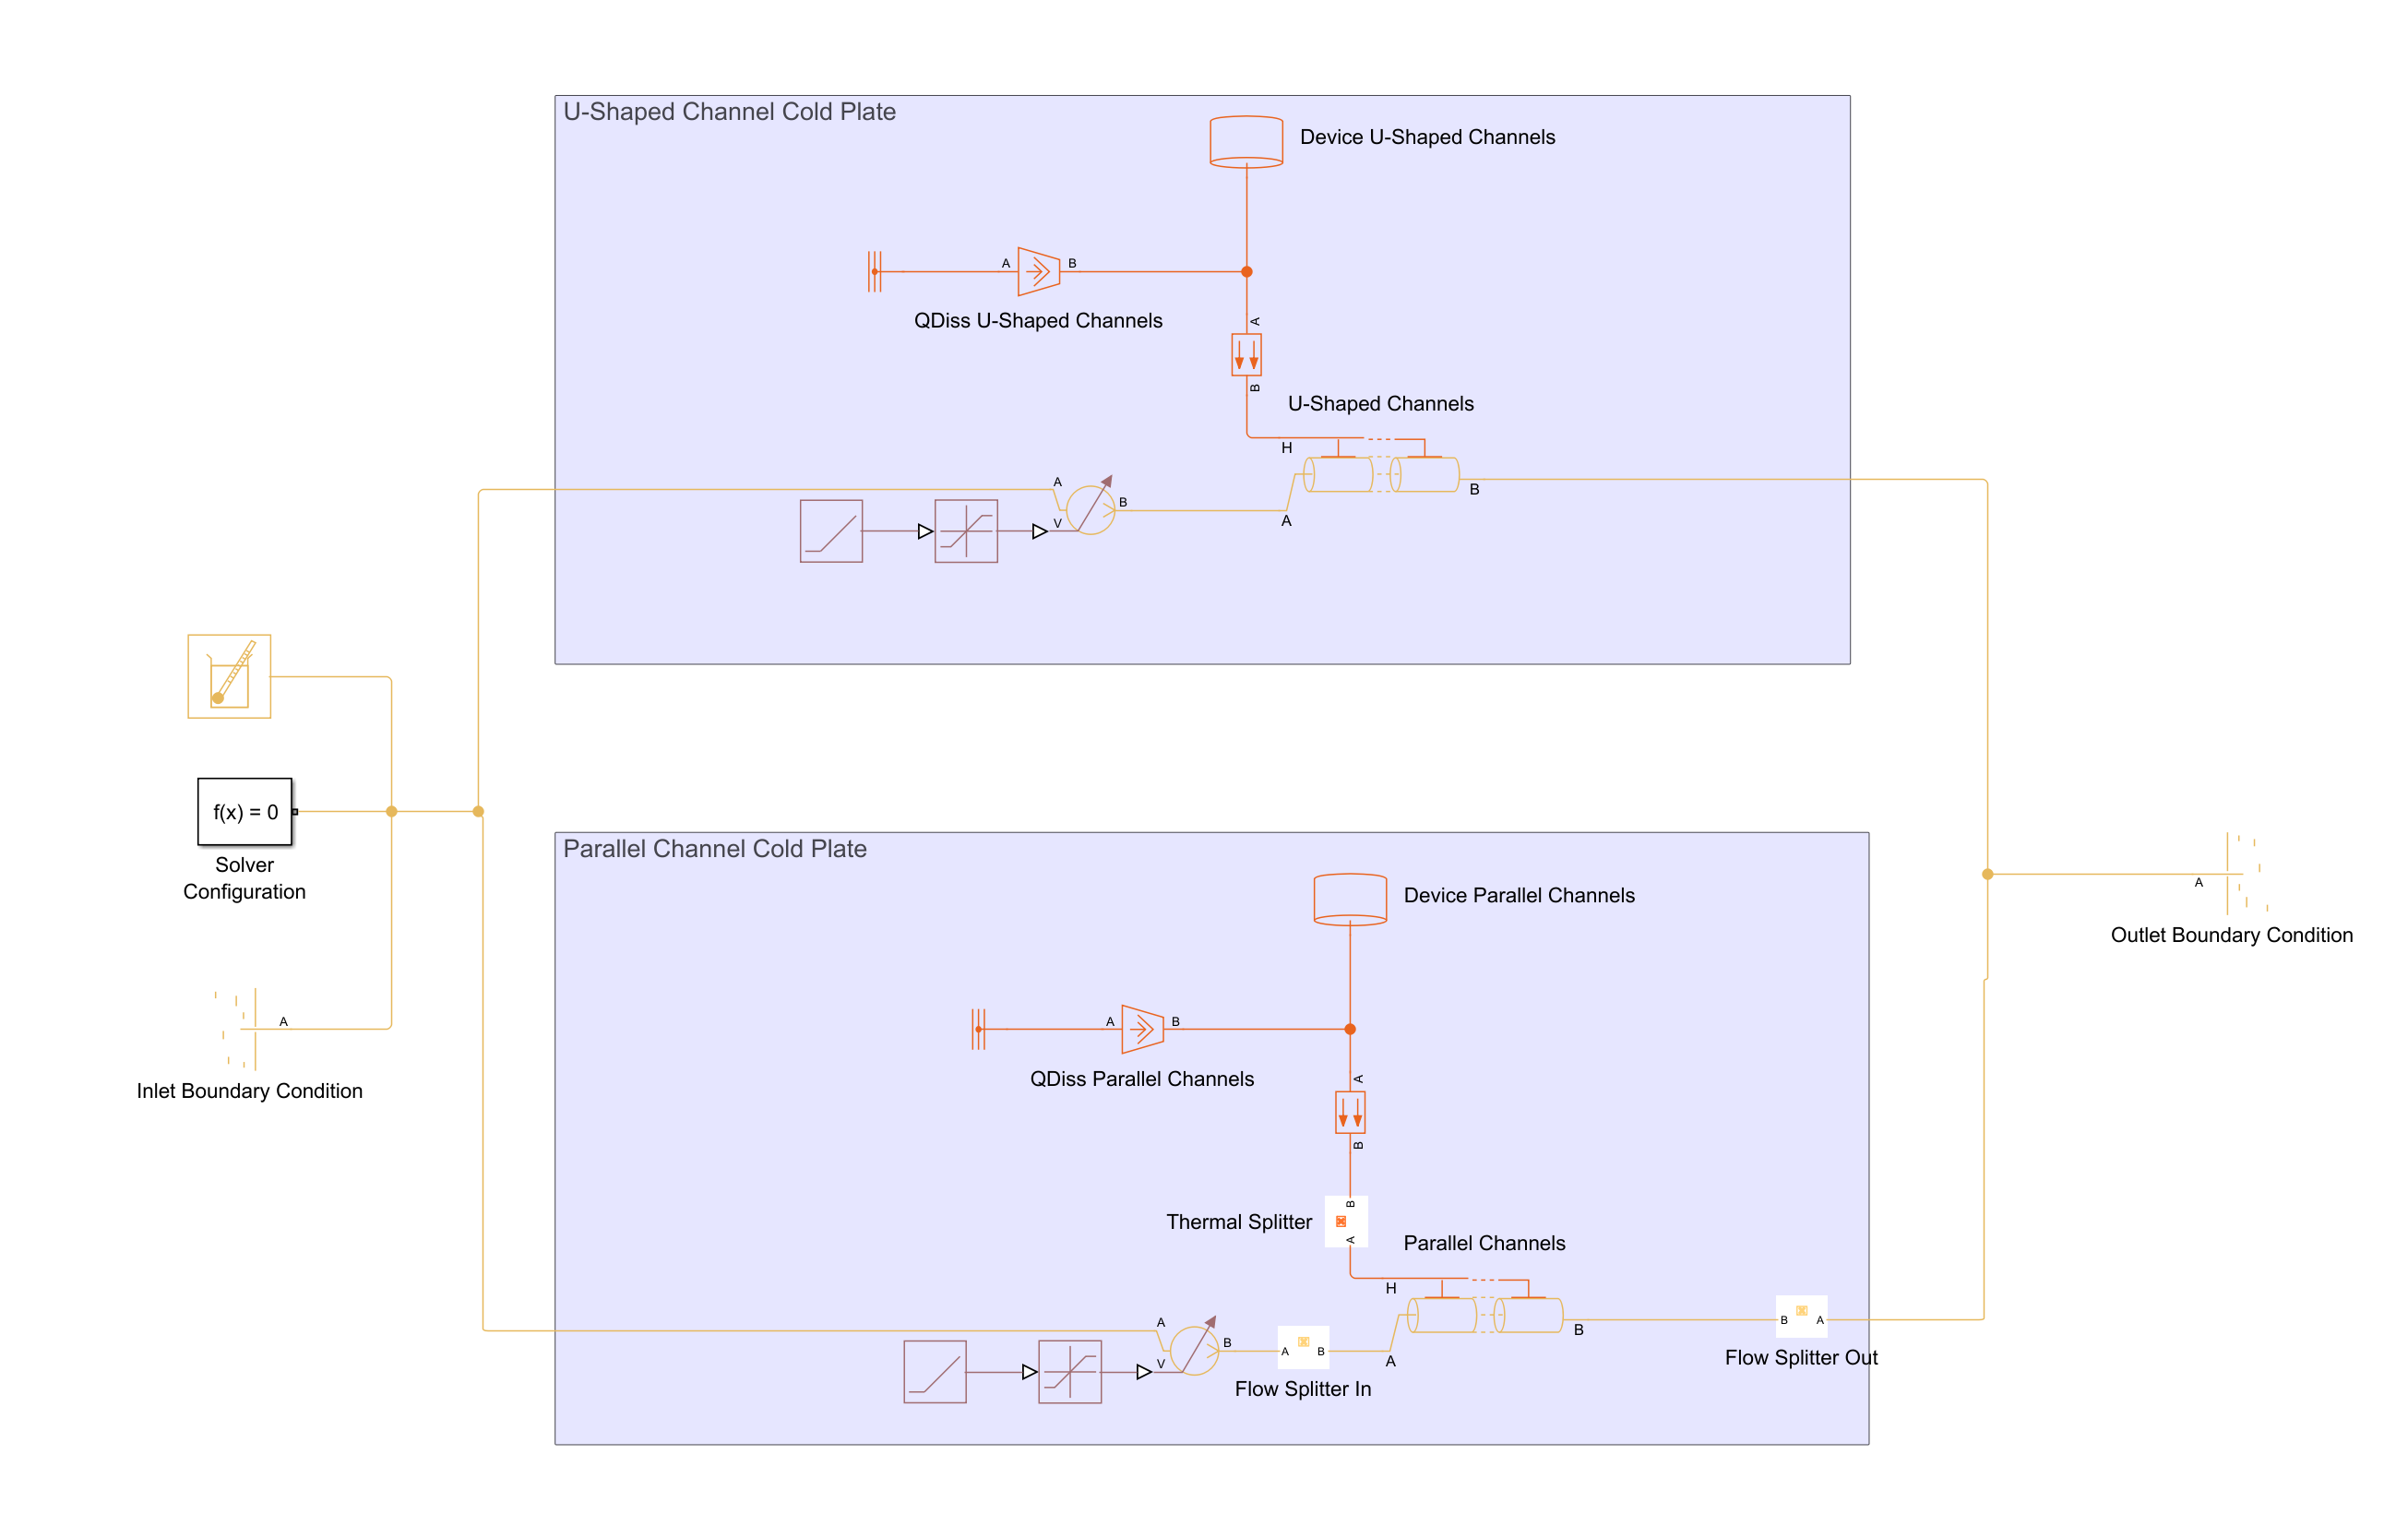

For both confugurations Pipe (TL) blocks are used to represent the geometry. Note that for the parallal channel configurations a "Flow Splitter" component is added on both sides of the pipe, and a "Thermal Splitter" is added at the Pipe (TL) thermal node. Assuming the parallel channels have an equal geometry and the manifold is designed in such a way, that the flow is evenly split between flow channels, we can only model one channel, for such a case the Flow Splitter acts as a multiplier and divider to make sure in the thermal liquid domain the flow is divided at cold plate input and multiplied at output. Similarly the Thermal Splitter will divide the heat flow rate into the pipe. The multiplying and dividing factor will be the number of parallel channels. Both splitters are provided as a custom library:

open_system(projRoot + "\Libraries\supplemental_lib.slx")

For the parameteric sweep a [Simulink.SimulationInput](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput.html) object is used. In this model the Model Workspace is already populated with parameters needed by the model, that have been defined in the [ColdPlate](matlab:open('.\ColdPlate.mlx')), this avoids having to transfer base workspace variables to parallel workers when using parallel simulations in the next step. Additional parameters used include:

mdlName = "example_compareColdPlates";
clear simInp

% Pre-allocate SimulationInput
simInp(numel(cpLength),numel(cpWidth), numel(channelWidth)) = Simulink.SimulationInput(mdlName);

for i = 1:numel(cpLength)
    for j = 1:numel(cpWidth)
        for k = 1:numel(channelWidth)

            channelPitch = channelWidth(k) + simscape.Value(3, "mm");
            % U-shaped channels
            effFlowLengthU        = cpLength(i) - 2*channelMargin;                                    % Effective flow length of channels for U-shaped configuration
            numPassesU            = floor((cpWidth(j) - 2*channelMargin)/(2*channelPitch));           % Number of channel "U" passes based on the channel pitch for U-shaped configuration
            channelLengthU        = numPassesU*2*effFlowLengthU;                                      % Derived total channel length for U-shaped configuration

            % Parallel channels
            channelLengthP        = cpWidth(j) - 2*channelMargin;                                     % Flow length of each parallel channel for parallel configuration
            numChannelsP          = floor((cpLength(i) - 2*channelMargin)/channelPitch);

            % Shared parameters
            channelArea           = channelHeight*channelWidth(k);                                    % Channel cross-sectional area
            channelDh             = 2*channelWidth(k)*channelHeight/(channelHeight+channelWidth(k));  % Channel hydraulic diameter

            % Calculating additional equivalent length to determine pressure drop
            % U-shaped channels
            numBendU              = numPassesU*4;                                                     % Number of 90 degree bends in U-shaped configuration
            equivalentLengthU     = numBendU*60*channelDh;                                            % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow
            % Parallel channels
            numBendP              = 2;                                                                % Number of 90 degree bends in parallel channel configuration
            equivalentLengthP     = numBendP*60*channelDh;                                            % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow
            

            % Populating the Simulation.Input with variables, additionaly a
            % PostSimFcn is set to calculate device temperature and cold
            % plate pressure drop for every run (see function at bottom of
            % this script)
            simInp(i,j,k)         = Simulink.SimulationInput(mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("cpLength", cpLength(i).value("mm"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("cpWidth", cpWidth(j).value("mm"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channelWidth", channelWidth(k).value("mm"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channelLengthU", channelLengthU.value("m"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channelLengthP", channelLengthP.value("m"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("equivalentLengthU", equivalentLengthU.value("m"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("equivalentLengthP", equivalentLengthP.value("m"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("numChannelsP", numChannelsP, "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channelArea", channelArea.value("mm^2"), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setPostSimFcn(@(simOut)postSimFcn(simOut));
        end
    end
end


#### Running the parameter sweep

The function [parsim](https://www.mathworks.com/help/releases/R2025b/simulink/slref/parsim.html?searchHighlight=parsim&s_tid=doc_srchtitle) allows to speed up the simulation by parallelizing the runs, of Parallel Computing Toolbox is not available the simulations will be carried out in serial. The Simulation Manager is visualized during the run which allows to monitor the simluations and visualize model output, for example from the post-processing function:

simOut = parsim(simInp, UseFastRestart="on", ShowSimulationManager ="on" , ShowProgress="off");

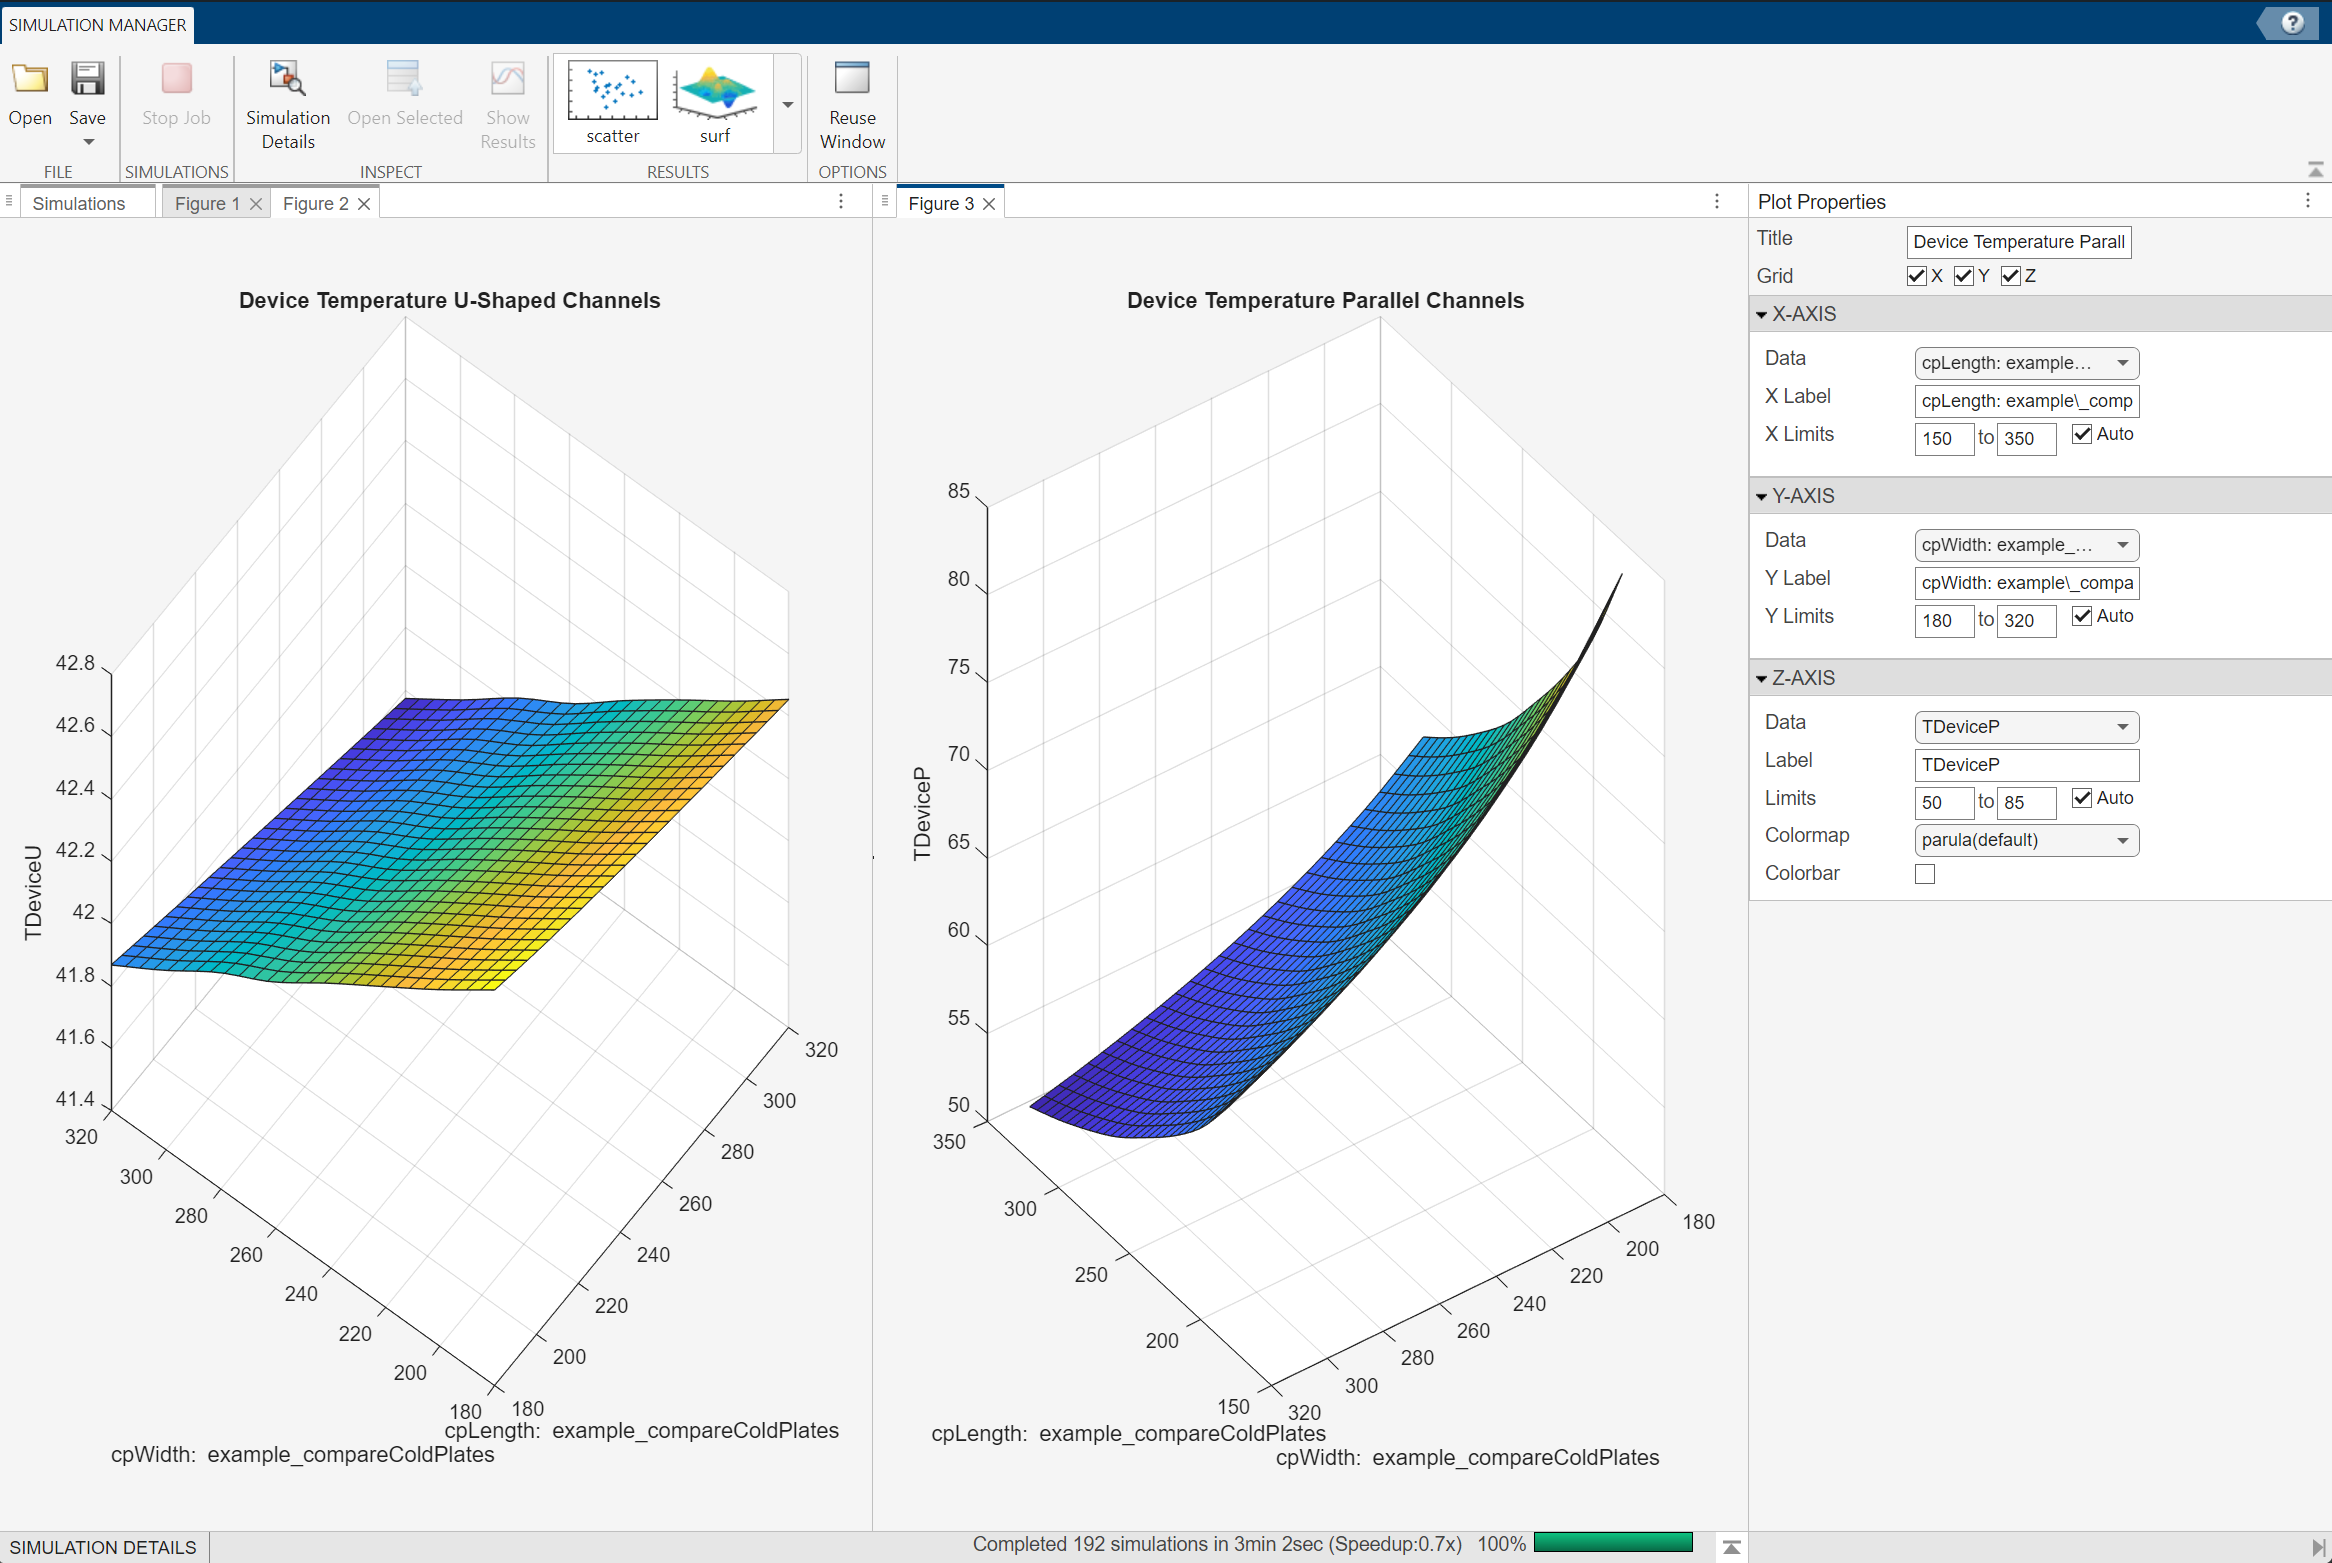

Notice that for the given parameter set the Simulation Manager gives an error for one of the runs, you can investigate the error that was thrown by selecting the repsective run in the *Simulations* tab and going to the *Diagnostics* tab:

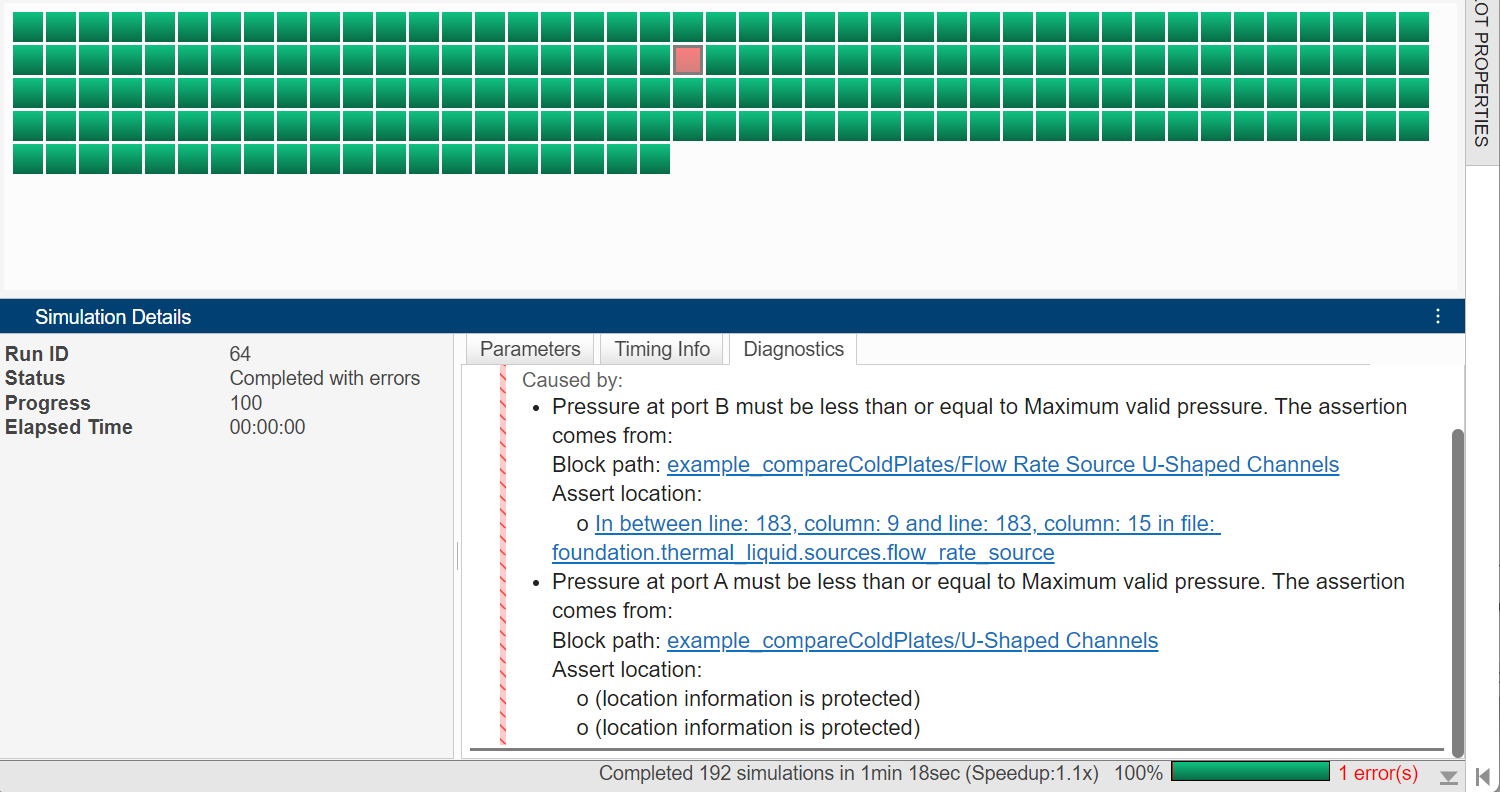

The pipe block representing the U-shapes channels simulated a pressure that was outside the valid region, the valid region is defined by the selected fluid in the [Thermal Liquid Properties (TL)](https://www.mathworks.com/help/releases/R2025b/hydro/ref/thermalliquidpropertiestl.html) block amd its properties range. In this case the error is likely a result from the U-shaped channel creating a very large pressure drop. Looking at the *Parameters* tab, we can see that the run is related to the smallest channel width and the largest cold plate width and length, meaning the longest cold plate channel with the smallest width, resulting in the largest pressure drop for the given parameter set. Note that in the Thermal Liquid Properties (TL) block, you can set the parameter *Pressure and temperature outside valid range* to *Warning* or *None, *this would avoid the simulation to be stopped when the values are outside the valid range, and could be useful for investigations such as a parameter sweep. 

#### Visualize results

In this section we are extracting the final device temperature as well as the pressure drop across the geometry to compare both results and select a design. 

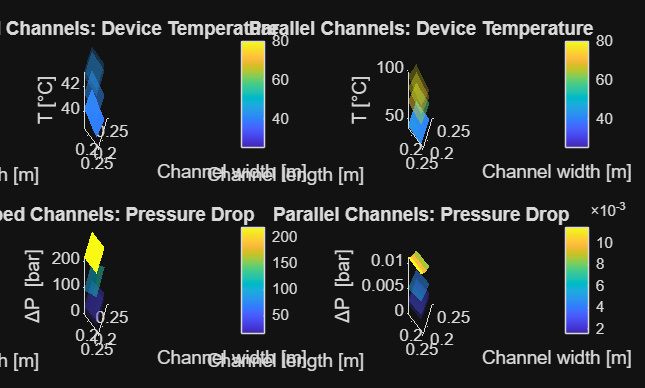

TDeviceU = reshape([simOut.TDeviceU],numel(cpLength), numel(cpWidth), numel(channelWidth));
TDeviceP = reshape([simOut.TDeviceP],numel(cpLength), numel(cpWidth), numel(channelWidth));
dpColdPlateU = reshape([simOut.dpColdPlateU],numel(cpLength), numel(cpWidth), numel(channelWidth));
dpColdPlateP = reshape([simOut.dpColdPlateP],numel(cpLength), numel(cpWidth), numel(channelWidth));


figure
tiledlayout(2,2)
nexttile
colormap hot
clim([25 80])

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value("m"),cpWidth.value("m"),TDeviceU(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title("U-Shaped Channels: Device Temperature")
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("T [°C]")
hold off


nexttile
colormap hot
clim([25 80])

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value("m"),cpWidth.value("m"),TDeviceP(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title("Parallel Channels: Device Temperature")
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("T [°C]")
hold off

nexttile
colormap parula

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value("m"),cpWidth.value("m"),dpColdPlateU(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title("U-Shaped Channels: Pressure Drop")
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("\DeltaP [bar]")

hold off

nexttile
colormap parula

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value("m"),cpWidth.value("m"),dpColdPlateP(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title("Parallel Channels: Pressure Drop")
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("\DeltaP [bar]")

hold off

We can see that the thermal performance is better in the U-shaped configuration, but it causes a significantly higher pressure drop, specifically in larger cold plate length in wisth parameters which are reasulting in a longer flow path. The parallel channels configuration typically has a better temperauture uniformity (not visible in these results, since the simulation model is not further discretized). The pressure drop is quite low, we reach the smallest device temperature for a smaller channel width and larger cold plate length and width, resulting in longer and more channels and a larger surface area. 

Based on this, we could continue with an optimization. For the purpose of this tutorial, we will select a suitable solution from the parameter sweep. 

For the following steps, we select a design with the following parameters:

and additionally

#### Post simulation function used in parameter sweep to calcuate additional derived outputs

function [newSimOut] = postSimFcn(simOut)
    newSimOut = simOut;
    TDeviceTemp = simOut.simlog.Device_U_Shaped_Channels.T.series.values("degC");
    newSimOut.TDeviceU = TDeviceTemp(end);
    TDeviceTemp = simOut.simlog.Device_Parallel_Channels.T.series.values("degC");
    newSimOut.TDeviceP = TDeviceTemp(end);
    
    pATemp = simOut.simlog.U_Shaped_Channels.A.p.series.values("bar");
    pBTemp = simOut.simlog.U_Shaped_Channels.B.p.series.values("bar");
    newSimOut.dpColdPlateU = pATemp(end)-pBTemp(end);
    
    pATemp = simOut.simlog.Parallel_Channels.A.p.series.values("bar");
    pBTemp = simOut.simlog.Parallel_Channels.B.p.series.values("bar");
    newSimOut.dpColdPlateP = pATemp(end)-pBTemp(end);

end